# Maximum Likelihood Estimation (MLE)

**Computational Psychiatry Course (CPC) 2023**

**Title:            Maximum Likelihood Estimation **

**Speaker:     Florian Schönleitner**

% clean workspace 
clear all
close all

% fix RNG seed
rng(10);

This script illustrates the overfitting problem occuring when using pure Maximum Likelihood Estimation (MLE). We here use the example of synthetic data that is generated from a low-order polynomial and fitted with polynomials of different order.  We will consider polynomial models of order P:


$$y=\theta_o +\theta_1 x+\theta_2 x^2 +\;\ldotp \ldotp \ldotp +{\;\theta }_P x^P +\epsilon \;=\;\;\mathit{\mathbf{x}}\theta +\epsilon \;$$


where $\mathit{\mathbf{x}}=\left(x,x^{2\;} ,\;\ldotp \ldotp \ldotp ,x^{P\;} \right)$, $\theta ={\left(\theta_0 ,\theta_1 ,\ldotp \ldotp \ldotp ,\theta_P \;\;\right)}^{T\;}$, and $\epsilon \sim \mathcal{N}\;\left(0,\sigma^2 \;\right)$ iid. The MLE for the polynomial model is given by: 


$$\theta_{\textrm{MLE}} ={\left({\mathit{\mathbf{X}}}^T \mathit{\mathbf{X}}\right)}^{-1} {\mathit{\mathbf{X}}}^T \mathit{\mathbf{y}}$$


The log-likelihood for the polynomial model is given by:


$$\log \;p\left(\mathit{\mathbf{y}}|\theta \;\right)=-\frac{N}{2}\log \left(2\pi \;\sigma^2 \right)-\frac{{\left(\mathit{\mathbf{y}}-X\theta \right)}^T \left(\mathit{\mathbf{y}}-X\theta \right)}{2\sigma^2 }$$


% ML estimator for theta
ml = @(y,X,sigma) (X'*X)\(X'*y);

% log-likelihood function
llh = @(y,X,sigma,theta) -numel(y)*log(2*pi*sigma^2)/2 - sum((y-X*theta).^2)/(2*sigma^2);

Next, we need to implement the the data-generating process in order to simulate some observations. 

% data-generating process
DGP = @(x,theta, sigma) bsxfun(@power,x,0:numel(theta(2:end)))*theta + sigma*randn(size(x));

% simulate some observations
x = (-.5:.1:.2)';
theta = [.3; -.1; .5];
sigma = sqrt(.001);
y = DGP(x,theta,sigma);

% define the polynomial orders
Ps  = [1 2 7];

% results arrays
llhTrain = zeros(1,numel(Ps));
thetaMls    = cell(numel(Ps),1);

% iterate over polynomial orders
for ip = 1:numel(Ps)
    
    % design matrix
    P = Ps(ip);
    X = bsxfun(@power,x,0:P);
    
    % ML estimates
    thetaMls{ip}   = ml(y,X,sigma);
   
    % evaluate log likelihood at the ML estimates
    llhTrain(ip) = llh(y,X,sigma,thetaMls{ip});
end

Let's plot the results for the ML approach and have a look at the simulated and estimated data as well as the parameter estimates for the models. 

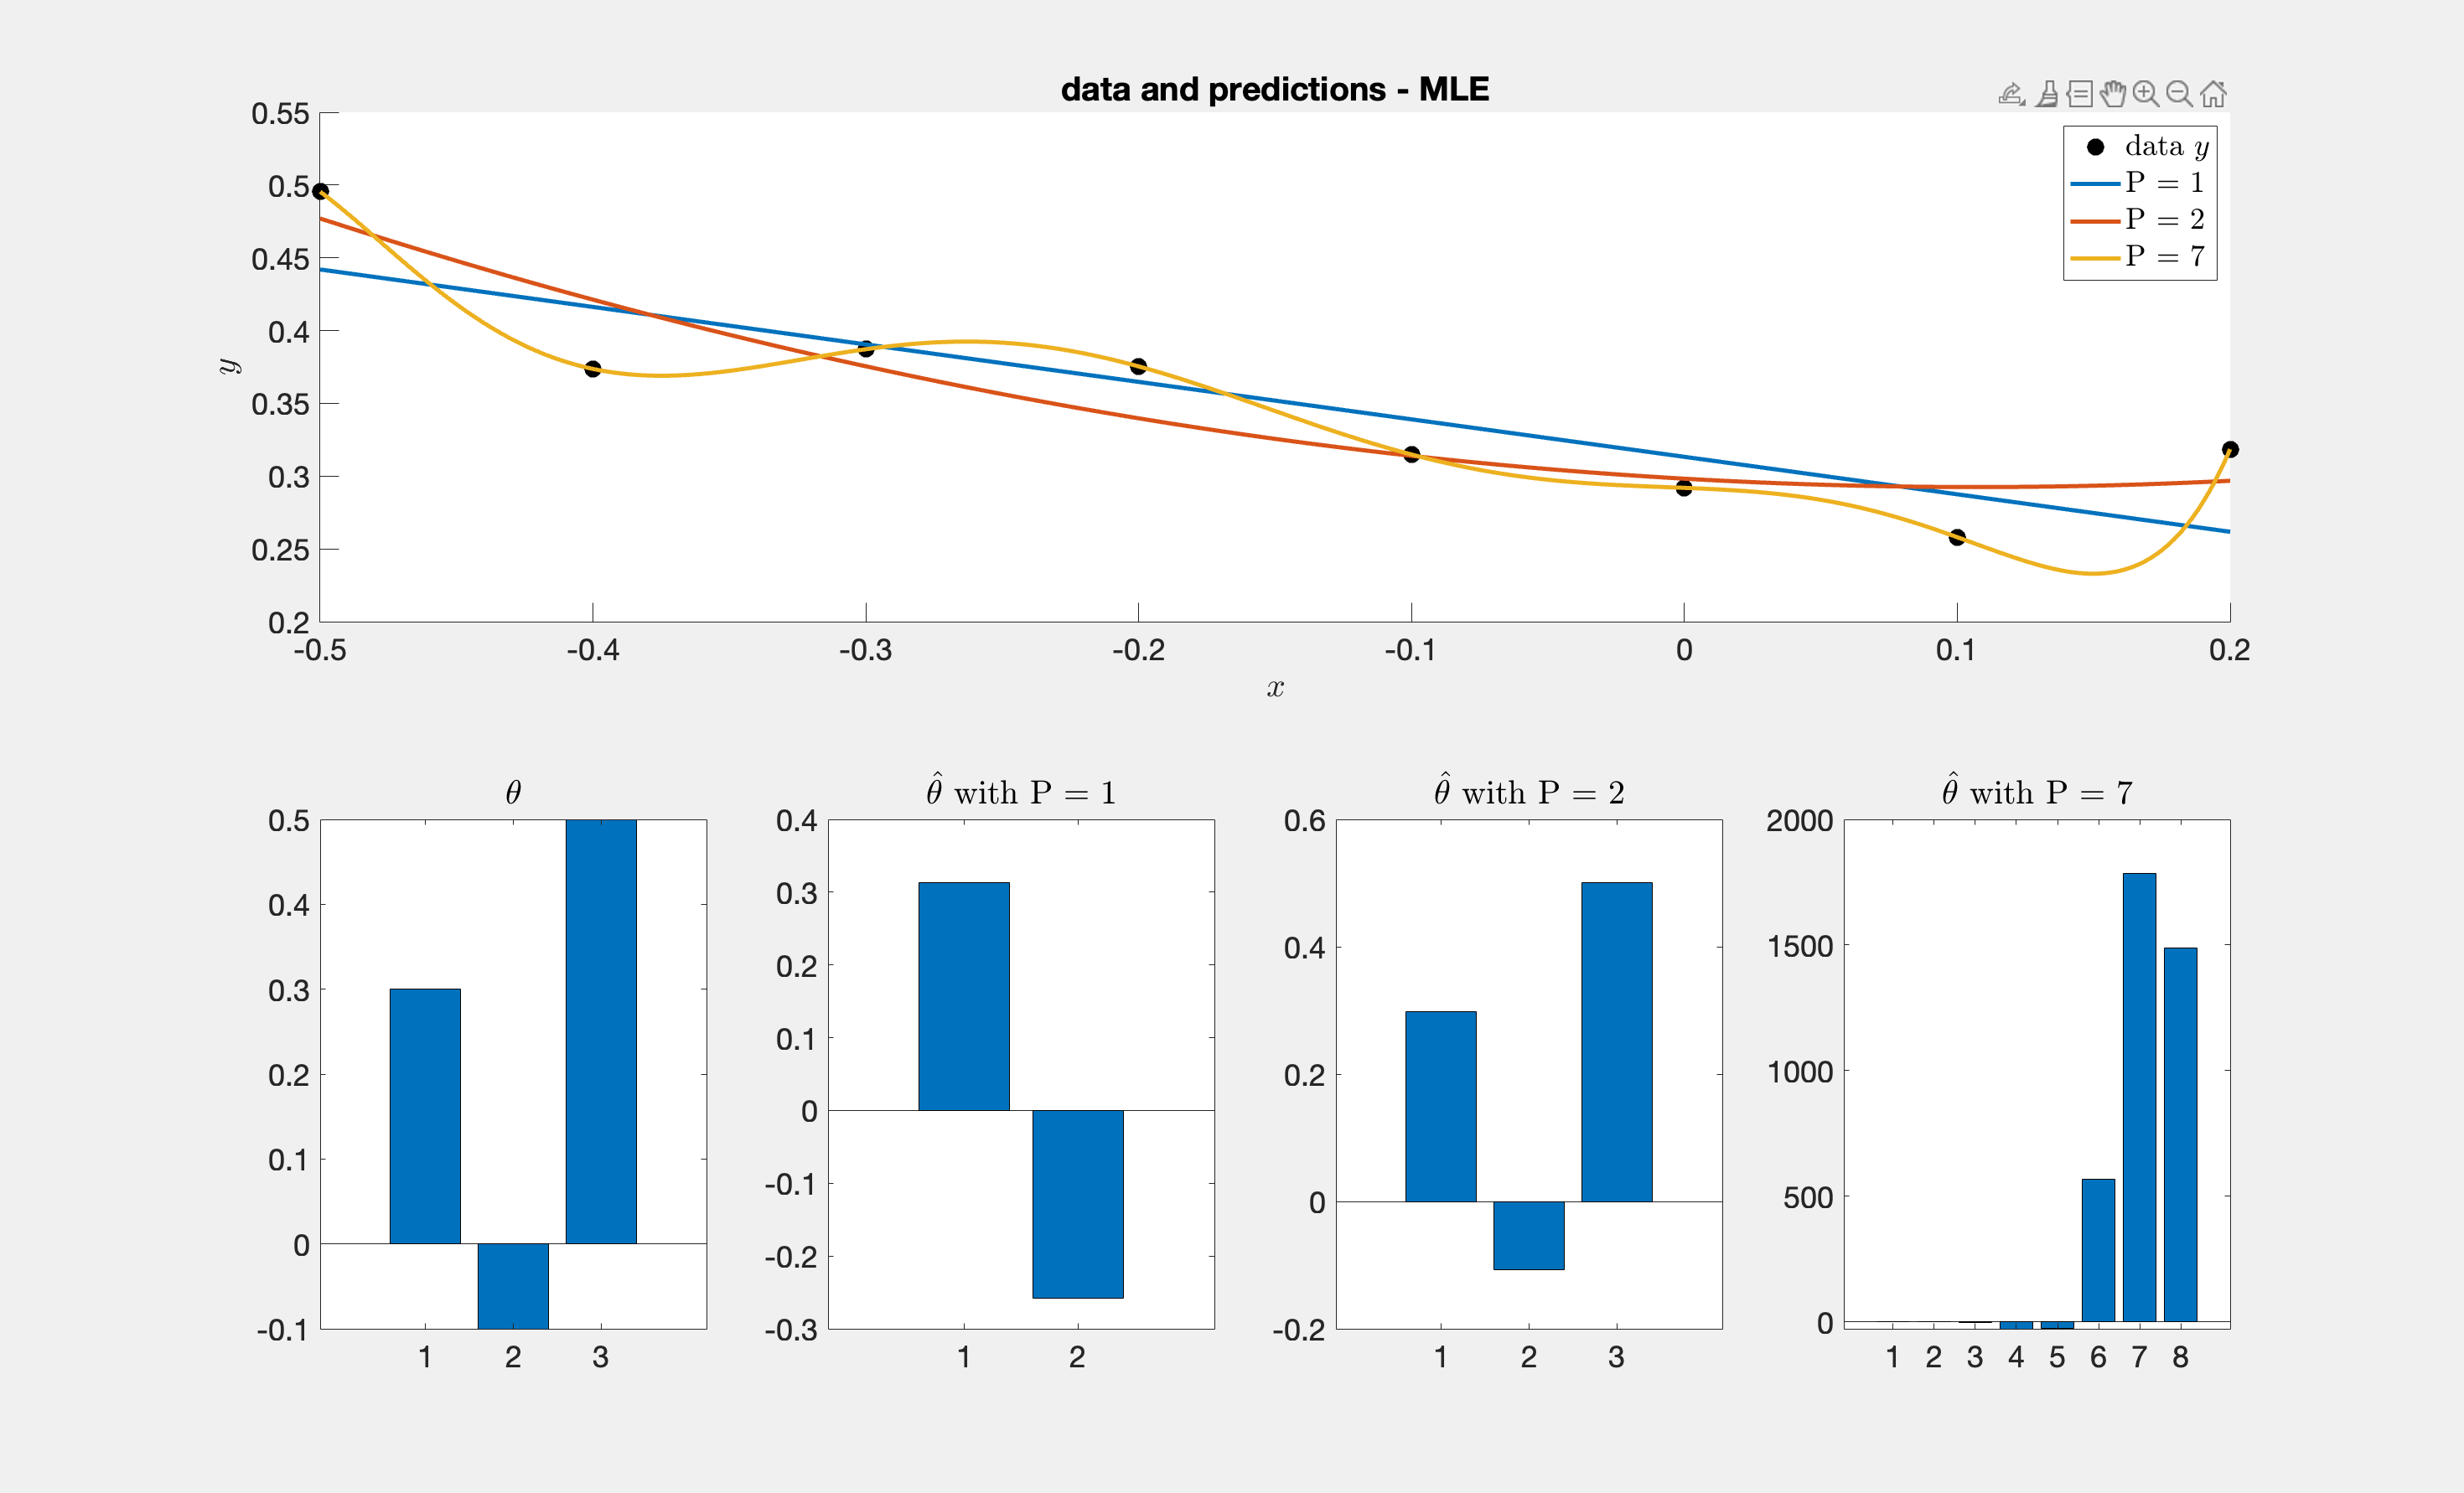

figure('units','normalized','outerposition',[0 0 1 1], 'Name','MLE predictions');

% color for each model 
cmap = colormap("lines");
colors = cell(numel(Ps),1);
for ip = 1:numel(Ps)
    colors{ip} = cmap(ip,:);
end

% increase the resolution when plotting the model estimates
x_plt = (-.5:.001:.2)';

% plot simulated data 
ax1 = subplot(2,1,1);
hold on
plot(x,y,LineStyle='none', Marker='o', MarkerSize=10, MarkerFaceColor='k', MarkerEdgeColor='k');
ylim([0.2 0.5])
title('data and predictions - MLE', FontSize=20);
ylabel('$y$','Interpreter','latex', FontSize=18)
xlabel('$x$','Interpreter','latex', FontSize=18)
llabels = {'data $y$'};
legend(llabels, Interpreter="latex", FontSize=18)
ax = gca;
ax.FontSize = 18;

subplot(2,4,5);
bar(1:3,theta)
title('$\theta$',Interpreter='latex', FontSize=20)
ax = gca;
ax.FontSize = 18;

% plot model predictions
for ip = 1:numel(Ps)
    waitforbuttonpress;

    subplot(2,1,1);
    P = Ps(ip);
    X = bsxfun(@power,x_plt,0:P);
    plot(ax1,x_plt,X*thetaMls{ip}, LineWidth=2.5, Color=colors{ip});
    ylim([0.2 0.55])
    llabels{end+1} = ['P = ' num2str(Ps(ip))];
    legend(llabels, Interpreter="latex", FontSize=18)

    subplot(2,4,ip+5);
    bar(1:Ps(ip)+1,thetaMls{ip})
    title(['$\hat{\theta}$ with P = ' num2str(Ps(ip))],Interpreter='latex', FontSize=18)
    ax = gca;
    ax.FontSize = 18;
end
hold off

The upper plot clearly shows that the polynomial model of order P=7 strongly overfits the data! This is due to the unregularized ML estimation of parameter values theta, which show very large values far from the prior. Remeber that the ML estimator does only depend on the data and design matrix but **not on the prior**!

% define the polynomial orders and number of repetition
Ps  = 0:7;
N = 100;

% results arrays
llhTrain = zeros(N,numel(Ps));

% ML estimates
thetaMls = cell(numel(Ps),N);

% compute results
for n=1:N   

    % generate new observations
    rng();
    y = DGP(x,theta,sigma);

    for ip = 1:numel(Ps)
        
        % design matrix
        P = Ps(ip);
        X = bsxfun(@power,x,0:P);
        
        % ML estimates
        thetaMls{ip,n}  = ml(y,X,sigma);
    
        % evaluate log likelihood at the ML estimates
        llhTrain(n,ip) = llh(y,X,sigma,thetaMls{ip,n});
    end
end


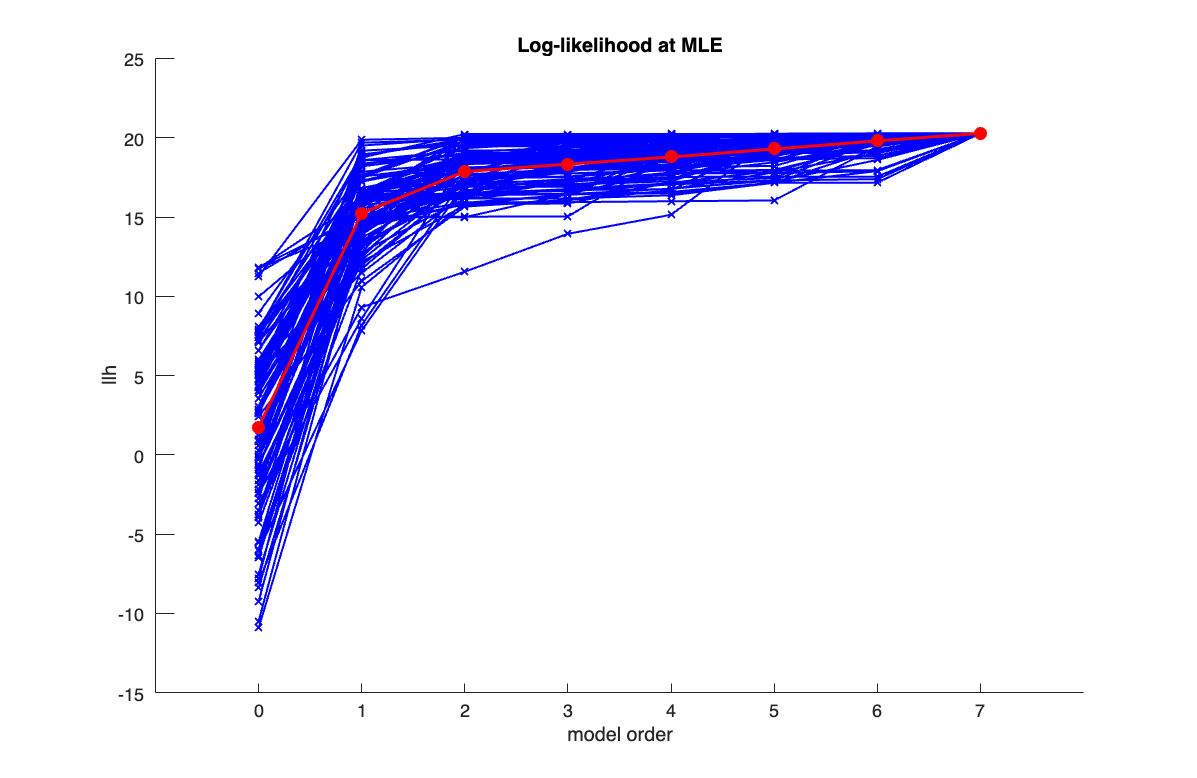

figure('units','normalized','outerposition',[0 0 1 1], 'Name', 'MLE log-likelihood');

% plot log likelihood
hold on
for ip = 1:size(llhTrain,1)
    plot(1:size(llhTrain,2),llhTrain(ip,:),'x-',...
        Color=[0 0 1 .1], MarkerSize=10, LineWidth=2)
end
plot(1:size(llhTrain,2),mean(llhTrain,1),'ro-',MarkerSize=10, ...
    MarkerFaceColor=[1 0 0] ,LineWidth=3)
xlim([0 numel(Ps)+1])
title('Log-likelihood at MLE','FontSize',20);
xlabel('model order','FontSize',18)
ylabel('llh','FontSize',18)
set(gca,'xtick',1:numel(Ps))
set(gca,'xticklabel',Ps)
ax = gca;
ax.FontSize = 18;
box off
hold off

Author: Florian Schönleitner, TNU, UZH & ETHZ - 2023

Copyright 2023 by Florian Schönleitner <schoenleitner@biomed.ee.ethz.ch>

Based on the original script by Stephan Frässle 

Licensed under GNU General Public License 3.0 or later.

Some rights reserved. See COPYING, AUTHORS.